%selezionare la n prova da plottare(se si è eseguita solo una prova inserire 1)
prova=1;
flag.boxplot=0;%(1)esegue i boxplot delle 6 prove effettuate: (0) non esegue quella porzione

%previsioni dati di test
figure
hold on
idx = indexTest(1):indexTest(end);
plot(datetime(datestr(time(indexTest))),PrevisioniTest(:,1),'b--','LineWidth',1.5);%era idx
legend(["Observed" "Forecast "+NetOption],"Location","best")

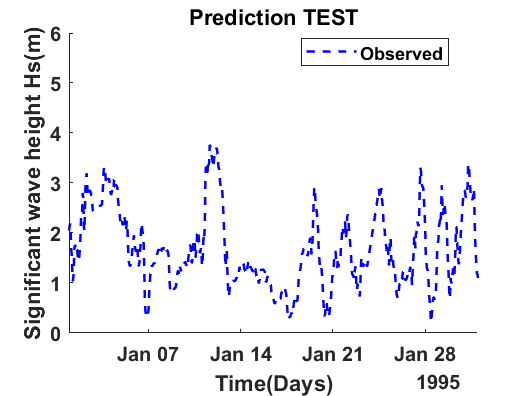

ylabel("Significant wave height Hs(m)");
xlabel("Time(Days)");
xlim([datetime(1995,01,1) datetime(1995,02,1)]);
ylim([0 6]);
title("Prediction TEST")
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');

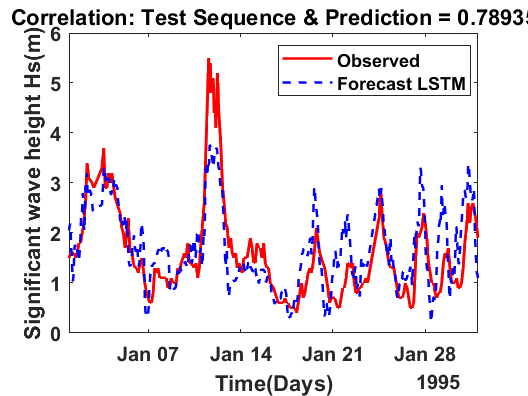




%paragone tra dati di test e predizione di essi
figure
plot(datetime(datestr(time(indexTest))),TestY(:,1),'r','LineWidth',1.5)%era idx
hold on
plot(datetime(datestr(time(indexTest))),PrevisioniTest(:,1),'b--','LineWidth',1.5);%era idx
legend(["Observed" "Forecast "+NetOption],"Location","best")
ylabel("Significant wave height Hs(m)");
xlabel("Time(Days)");
xlim([datetime(1995,01,1) datetime(1995,02,1)]);
title("Correlation: Test Sequence & Prediction = " + Parametri{prova,1}.rho)
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');

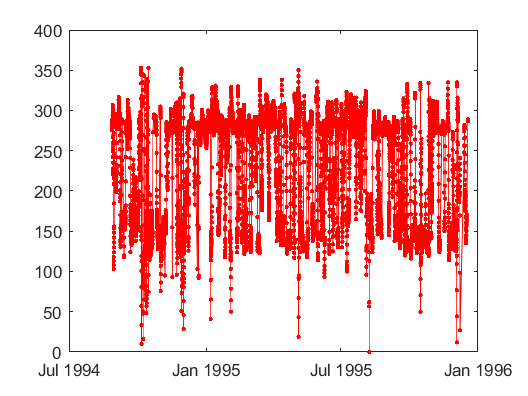




%Plotta la seconda uscita(dir)
figure
plot(datetime(datestr(time(idx))),TestY(:,2),'r.-','LineWidth',0.5)
hold on

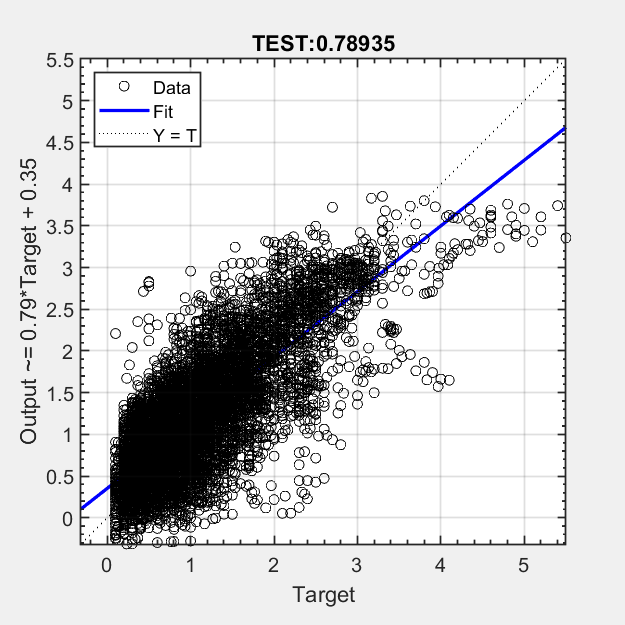

%grafici di regressione di test e train
figure
plotregression(con2seq(TestY(:,1)),con2seq(PrevisioniTest(:,1)))
title("TEST:"+ Parametri{prova,1}.rho)
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'in', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');

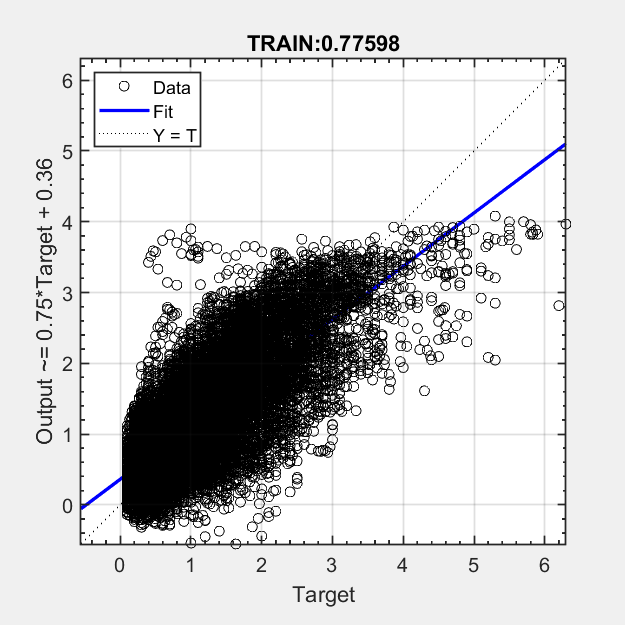




figure
plotregression(con2seq(TrainY_originale(:,1)),con2seq(PrevisioniTrain))
title("TRAIN:"+ Parametri{prova,1}.corrcoefTRAIN(1,2))
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'in', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');

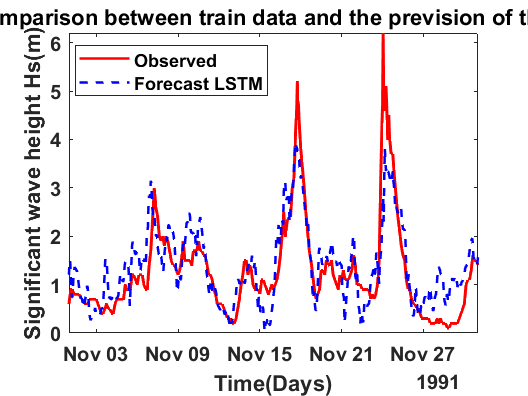

%Dati di train confrontati con le previsioni

figure
index= 1:numFeatures(4);
plot(datetime(datestr(time(indexTrain))),TrainY_originale(:,1),'r','LineWidth',1.5)
hold on
plot(datetime(datestr(time(indexTrain))),PrevisioniTrain(:,1),'b--','LineWidth',1.5);
legend(["Observed" "Forecast "+NetOption],"Location","best")
ylabel("Significant wave height Hs(m)");
xlabel("Time(Days)");
xlim([datetime(1991,11,1) datetime(1991,12,1)]);
title("Comparison between train data and the prevision of them ")
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');

## Creazione tabelle delle 6 prove effettuate

if flag.boxplot==1

load("D:\Documenti\Universita\MATLAB\Prova_LSTM_5x5.mat")
j=1;
for i=1:10
    Tabella_test{j,1}(i,1)=Parametri{i,1}.rho;
    Tabella_test{j,1}(i,2)=Parametri{i,1}.mseTEST;
    Tabella_test{j,1}(i,3)=Parametri{i,1}.PRME;
    Tabella_test{j,1}(i,4)=Parametri{i,1}.PMARE;
    Tabella_test{j,1}(i,5)=Parametri{i,1}.PRMSE;
    Tabella_test{j,1}(i,6)=Parametri{i,1}.auc_Test;
    Tabella_test{j,1}(i,7)=Parametri{i,1}.bias;
    Tabella_test{j,1}(i,8)=Parametri{i,1}.Ns;
    
    Tabella_train{j,1}(i,1)=Parametri{i,1}.corrcoefTRAIN(2,1);
    Tabella_train{j,1}(i,2)=Parametri{i,1}.mseTRAIN;
    Tabella_train{j,1}(i,3)=Parametri{i,1}.PRME_train;
    Tabella_train{j,1}(i,4)=Parametri{i,1}.PMARE_train;
    Tabella_train{j,1}(i,5)=Parametri{i,1}.PRMSE_train;
    Tabella_train{j,1}(i,6)=Parametri{i,1}.auc_Train;
    Tabella_train{j,1}(i,7)=Parametri{i,1}.bias_train;
    Tabella_train{j,1}(i,8)=Parametri{i,1}.Ns_train;
end

load("D:\Documenti\Universita\MATLAB\Prova_LSTM.mat")
j=2;
for i=1:10
    Tabella_test{j,1}(i,1)=Parametri{i,1}.rho;
    Tabella_test{j,1}(i,2)=Parametri{i,1}.mseTEST;
    Tabella_test{j,1}(i,3)=Parametri{i,1}.PRME;
    Tabella_test{j,1}(i,4)=Parametri{i,1}.PMARE;
    Tabella_test{j,1}(i,5)=Parametri{i,1}.PRMSE;
    Tabella_test{j,1}(i,6)=Parametri{i,1}.auc_Test;
    Tabella_test{j,1}(i,7)=Parametri{i,1}.bias;
    Tabella_test{j,1}(i,8)=Parametri{i,1}.Ns;
    
    Tabella_train{j,1}(i,1)=Parametri{i,1}.corrcoefTRAIN(2,1);
    Tabella_train{j,1}(i,2)=Parametri{i,1}.mseTRAIN;
    Tabella_train{j,1}(i,3)=Parametri{i,1}.PRME_train;
    Tabella_train{j,1}(i,4)=Parametri{i,1}.PMARE_train;
    Tabella_train{j,1}(i,5)=Parametri{i,1}.PRMSE_train;
    Tabella_train{j,1}(i,6)=Parametri{i,1}.auc_Train;
    Tabella_train{j,1}(i,7)=Parametri{i,1}.bias_train;
    Tabella_train{j,1}(i,8)=Parametri{i,1}.Ns_train;
end

load("D:\Documenti\Universita\MATLAB\prova_Network1.mat")
j=3;
for i=1:10
    Tabella_test{j,1}(i,1)=Parametri{i,1}.rho;
    Tabella_test{j,1}(i,2)=Parametri{i,1}.mseTEST;
    Tabella_test{j,1}(i,3)=Parametri{i,1}.PRME;
    Tabella_test{j,1}(i,4)=Parametri{i,1}.PMARE;
    Tabella_test{j,1}(i,5)=Parametri{i,1}.PRMSE;
    Tabella_test{j,1}(i,6)=Parametri{i,1}.auc_Test;
    Tabella_test{j,1}(i,7)=Parametri{i,1}.bias;
    Tabella_test{j,1}(i,8)=Parametri{i,1}.Ns;
    
    Tabella_train{j,1}(i,1)=Parametri{i,1}.corrcoefTRAIN(2,1);
    Tabella_train{j,1}(i,2)=Parametri{i,1}.mseTRAIN;
    Tabella_train{j,1}(i,3)=Parametri{i,1}.PRME_train;
    Tabella_train{j,1}(i,4)=Parametri{i,1}.PMARE_train;
    Tabella_train{j,1}(i,5)=Parametri{i,1}.PRMSE_train;
    Tabella_train{j,1}(i,6)=Parametri{i,1}.auc_Train;
    Tabella_train{j,1}(i,7)=Parametri{i,1}.bias_train;
    Tabella_train{j,1}(i,8)=Parametri{i,1}.Ns_train;
end

load("D:\Documenti\Universita\MATLAB\Prova_Network2.mat")
j=4;
for i=1:10
    Tabella_test{j,1}(i,1)=Parametri{i,1}.rho;
    Tabella_test{j,1}(i,2)=Parametri{i,1}.mseTEST;
    Tabella_test{j,1}(i,3)=Parametri{i,1}.PRME;
    Tabella_test{j,1}(i,4)=Parametri{i,1}.PMARE;
    Tabella_test{j,1}(i,5)=Parametri{i,1}.PRMSE;
    Tabella_test{j,1}(i,6)=Parametri{i,1}.auc_Test;
    Tabella_test{j,1}(i,7)=Parametri{i,1}.bias;
    Tabella_test{j,1}(i,8)=Parametri{i,1}.Ns;
    
    Tabella_train{j,1}(i,1)=Parametri{i,1}.corrcoefTRAIN(2,1);
    Tabella_train{j,1}(i,2)=Parametri{i,1}.mseTRAIN;
    Tabella_train{j,1}(i,3)=Parametri{i,1}.PRME_train;
    Tabella_train{j,1}(i,4)=Parametri{i,1}.PMARE_train;
    Tabella_train{j,1}(i,5)=Parametri{i,1}.PRMSE_train;
    Tabella_train{j,1}(i,6)=Parametri{i,1}.auc_Train;
    Tabella_train{j,1}(i,7)=Parametri{i,1}.bias_train;
    Tabella_train{j,1}(i,8)=Parametri{i,1}.Ns_train;
end

load("D:\Documenti\Universita\MATLAB\Prova_Network3.mat")
j=5;
for i=1:10
    Tabella_test{j,1}(i,1)=Parametri{i,1}.rho;
    Tabella_test{j,1}(i,2)=Parametri{i,1}.mseTEST;
    Tabella_test{j,1}(i,3)=Parametri{i,1}.PRME;
    Tabella_test{j,1}(i,4)=Parametri{i,1}.PMARE;
    Tabella_test{j,1}(i,5)=Parametri{i,1}.PRMSE;
    Tabella_test{j,1}(i,6)=Parametri{i,1}.auc_Test;
    Tabella_test{j,1}(i,7)=Parametri{i,1}.bias;
    Tabella_test{j,1}(i,8)=Parametri{i,1}.Ns;
    
    Tabella_train{j,1}(i,1)=Parametri{i,1}.corrcoefTRAIN(2,1);
    Tabella_train{j,1}(i,2)=Parametri{i,1}.mseTRAIN;
    Tabella_train{j,1}(i,3)=Parametri{i,1}.PRME_train;
    Tabella_train{j,1}(i,4)=Parametri{i,1}.PMARE_train;
    Tabella_train{j,1}(i,5)=Parametri{i,1}.PRMSE_train;
    Tabella_train{j,1}(i,6)=Parametri{i,1}.auc_Train;
    Tabella_train{j,1}(i,7)=Parametri{i,1}.bias_train;
    Tabella_train{j,1}(i,8)=Parametri{i,1}.Ns_train;
end


load("D:\Documenti\Universita\MATLAB\Prova_Network4.mat")
j=6;
for i=1:10
    Tabella_test{j,1}(i,1)=Parametri{i,1}.rho;
    Tabella_test{j,1}(i,2)=Parametri{i,1}.mseTEST;
    Tabella_test{j,1}(i,3)=Parametri{i,1}.PRME;
    Tabella_test{j,1}(i,4)=Parametri{i,1}.PMARE;
    Tabella_test{j,1}(i,5)=Parametri{i,1}.PRMSE;
    Tabella_test{j,1}(i,6)=Parametri{i,1}.auc_Test;
    Tabella_test{j,1}(i,7)=Parametri{i,1}.bias;
    Tabella_test{j,1}(i,8)=Parametri{i,1}.Ns;
    
    Tabella_train{j,1}(i,1)=Parametri{i,1}.corrcoefTRAIN(2,1);
    Tabella_train{j,1}(i,2)=Parametri{i,1}.mseTRAIN;
    Tabella_train{j,1}(i,3)=Parametri{i,1}.PRME_train;
    Tabella_train{j,1}(i,4)=Parametri{i,1}.PMARE_train;
    Tabella_train{j,1}(i,5)=Parametri{i,1}.PRMSE_train;
    Tabella_train{j,1}(i,6)=Parametri{i,1}.auc_Train;
    Tabella_train{j,1}(i,7)=Parametri{i,1}.bias_train;
    Tabella_train{j,1}(i,8)=Parametri{i,1}.Ns_train;
end

## Creazione boxplot relativi alle 6 prove

for j=1:6
TEST.R(:,j)=Tabella_test{j,1}(:,1);
TEST.MSE(:,j)=Tabella_test{j,1}(:,2);
TEST.PRME(:,j)=Tabella_test{j,1}(:,3);
TEST.PMARE(:,j)=Tabella_test{j,1}(:,4);
TEST.PRMSE(:,j)=Tabella_test{j,1}(:,5);
TEST.AUC(:,j)=Tabella_test{j,1}(:,6);
TEST.BIAS(:,j)=Tabella_test{j,1}(:,7);
TEST.NS(:,j)=Tabella_test{j,1}(:,8);
end


for j=1:6
TRAIN.R(:,j)=Tabella_train{j,1}(:,1);
TRAIN.MSE(:,j)=Tabella_train{j,1}(:,2);
TRAIN.PRME(:,j)=Tabella_train{j,1}(:,3);
TRAIN.PMARE(:,j)=Tabella_train{j,1}(:,4);
TRAIN.PRMSE(:,j)=Tabella_train{j,1}(:,5);
TRAIN.AUC(:,j)=Tabella_train{j,1}(:,6);
TRAIN.BIAS(:,j)=Tabella_train{j,1}(:,7);
TRAIN.NS(:,j)=Tabella_train{j,1}(:,8);
end

figure(18)
t = tiledlayout(4,2);
title(t,"Parametri TEST")
nexttile
boxplot(TEST.R,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4" ])
title("R")
nexttile
boxplot(TEST.MSE,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4" ])
title("MSE")
nexttile
boxplot(TEST.PRME,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4" ])
title("PRME")
nexttile
boxplot(TEST.PMARE,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4" ])
title("PMARE")
nexttile
boxplot(TEST.PRMSE,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("PRMSE")
nexttile
boxplot(TEST.AUC,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4" ])
title("AUC")
nexttile
boxplot(TEST.BIAS,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("BIAS")
ylim([-0.15 0.15] )
nexttile
boxplot(TEST.NS,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("NS")

figure(19)
y = tiledlayout(4,2);
title(y,"Parametri TRAIN")
nexttile
boxplot(TRAIN.R,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("R")
nexttile
boxplot(TRAIN.MSE,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("MSE")
nexttile
boxplot(TRAIN.PRME,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("PRME")
nexttile
boxplot(TRAIN.PMARE,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("PMARE")
nexttile
boxplot(TRAIN.PRMSE,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("PRMSE")
nexttile
boxplot(TRAIN.AUC,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("AUC")
nexttile
boxplot(TRAIN.BIAS,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("BIAS")
ylim([-0.15 0.15])
nexttile
boxplot(TRAIN.NS,["LSTM-5X5" "LSTM" "Network1" "Network2" "Network3" "Network4"])
title("NS")

end